# Εργαστήριο Ψηφιακής Επεξεργασίας Σημάτων

## Συμπλήρωμα Αναφοράς 2ης Εργαστηριακής Άσκησης.

#### Λουδάρος Ιωάννης - 1067400

Εδώ περιλαμβάνεται ο κώδικας που χρησιμοποιήθηκε για την εκπόνηση της Άσκησης.

## Άσκηση 1

### fir1(.)

#### Χαμηλοπερατό

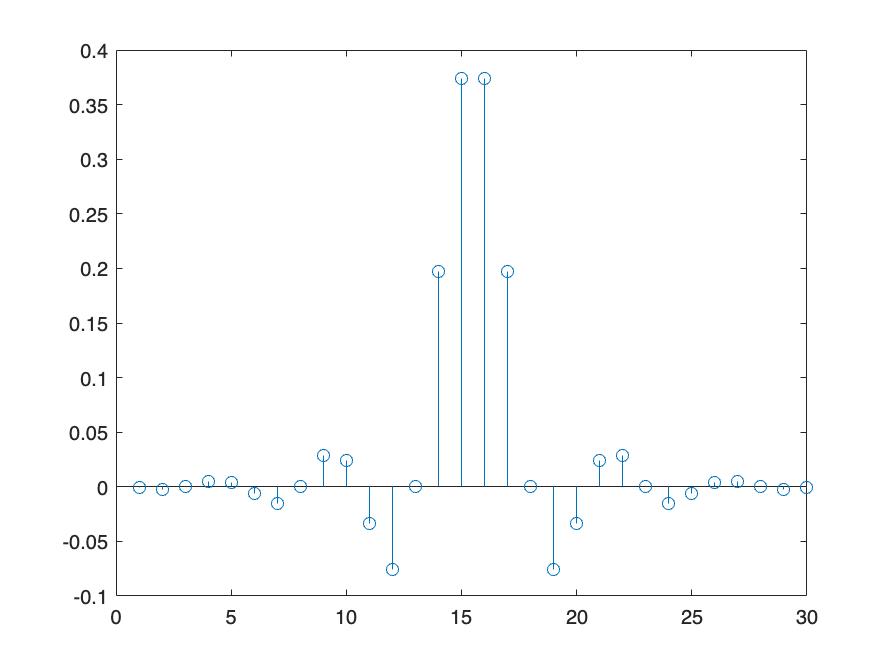

close all;clear;clc;

N = 30;
fc = 0.4;

hc = fir1(N-1,fc,'low');

stem(hc);

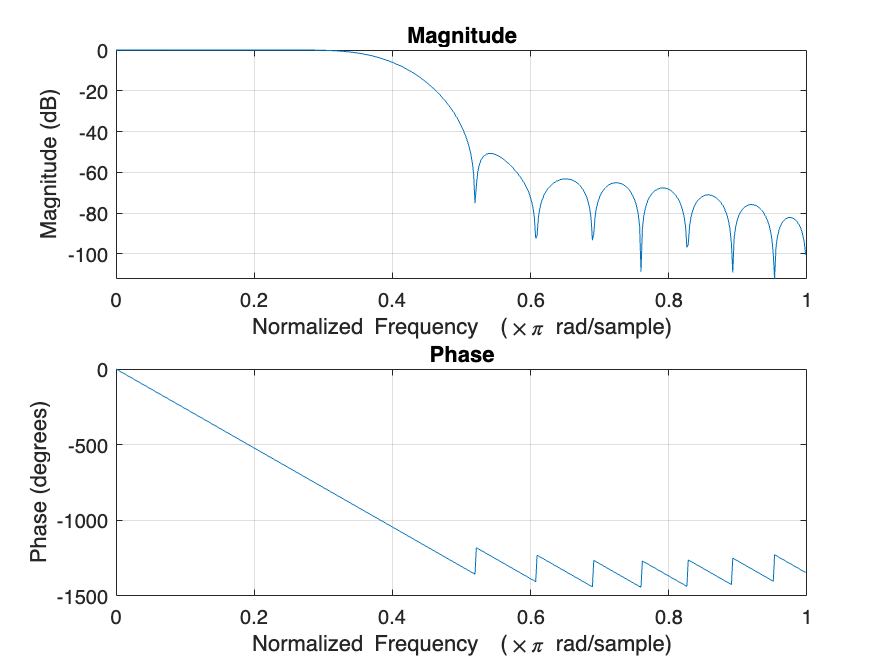


freqz(hc,1,512);

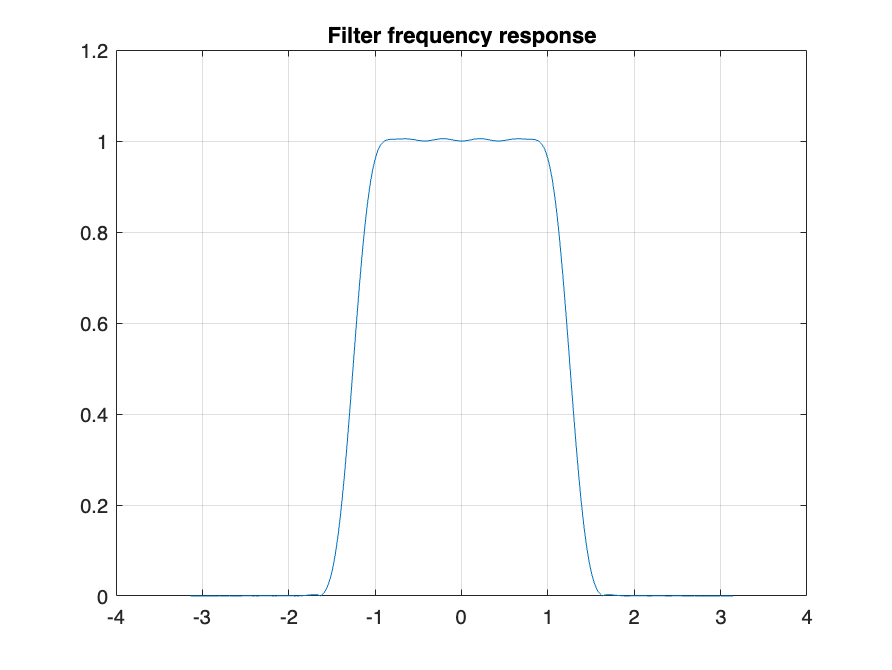


NumFFT = 4096;
Freqs = linspace(-pi,pi,NumFFT);

figure
plot(Freqs, abs(fftshift(fft(hc,NumFFT))));
title('Filter frequency response')
grid on

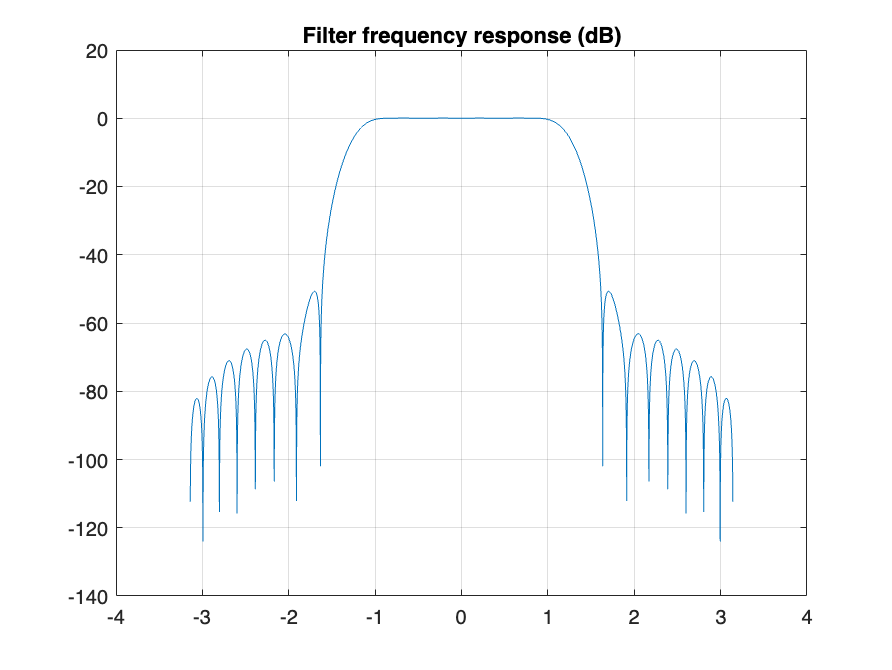


figure
plot(Freqs, 20*log10(abs(fftshift(fft(hc,NumFFT)))));
title('Filter frequency response (dB)')
grid on

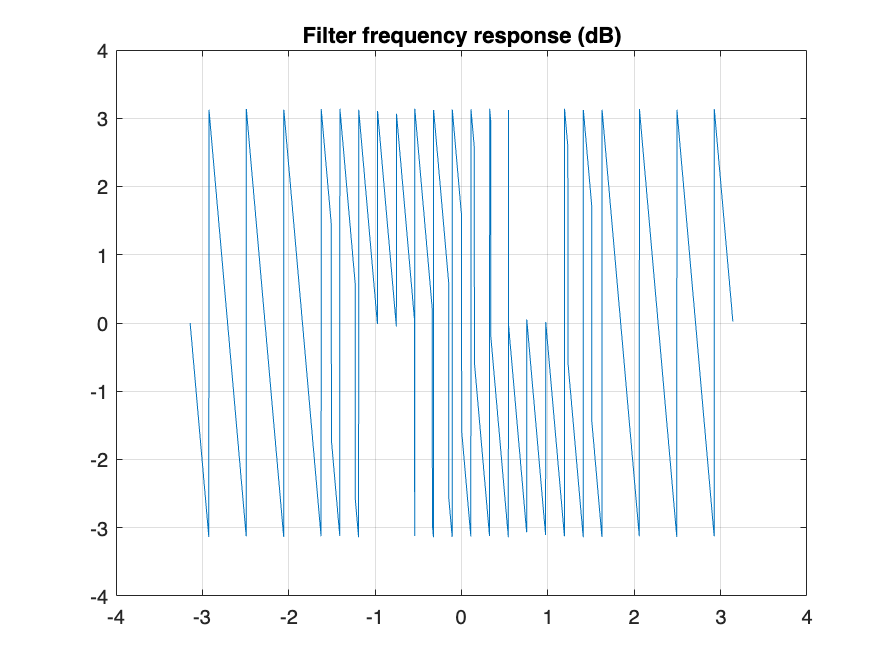


figure
plot(Freqs, angle(fft(hc,NumFFT)));
title('Filter frequency response (dB)')
grid on

#### Υψηπερατό

hc = fir1(N-1,fc,'high');

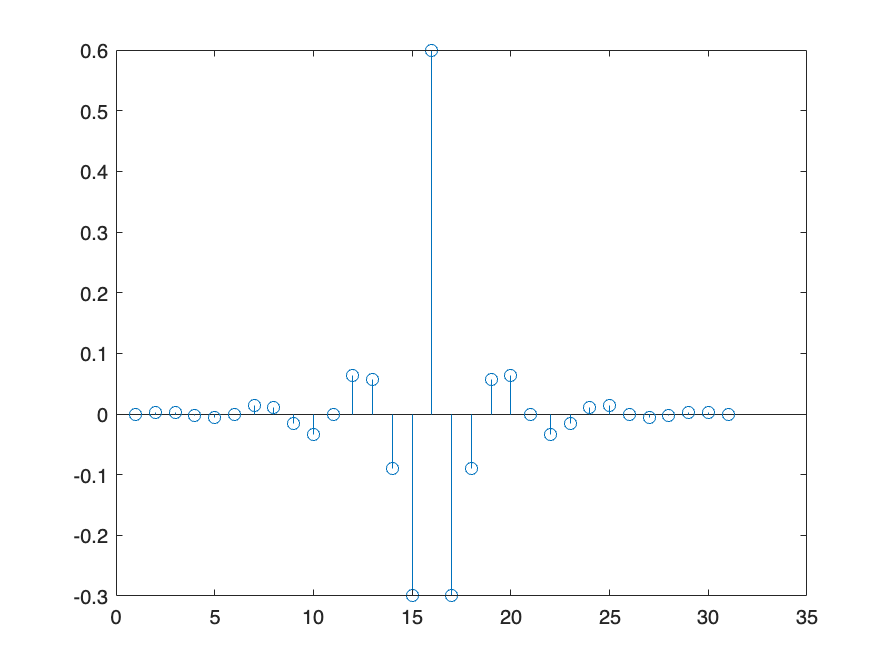


stem(hc);

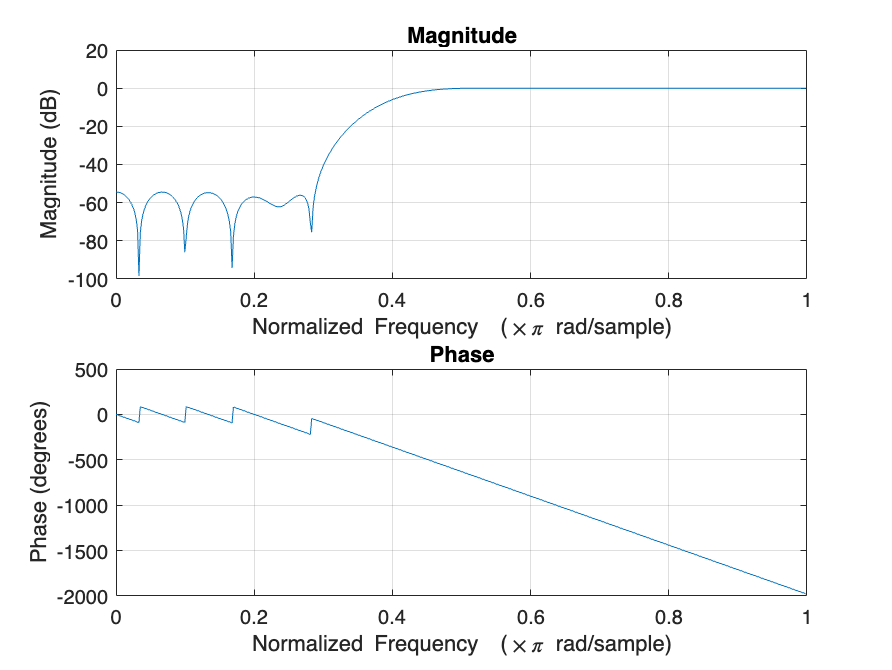


freqz(hc,1,512);

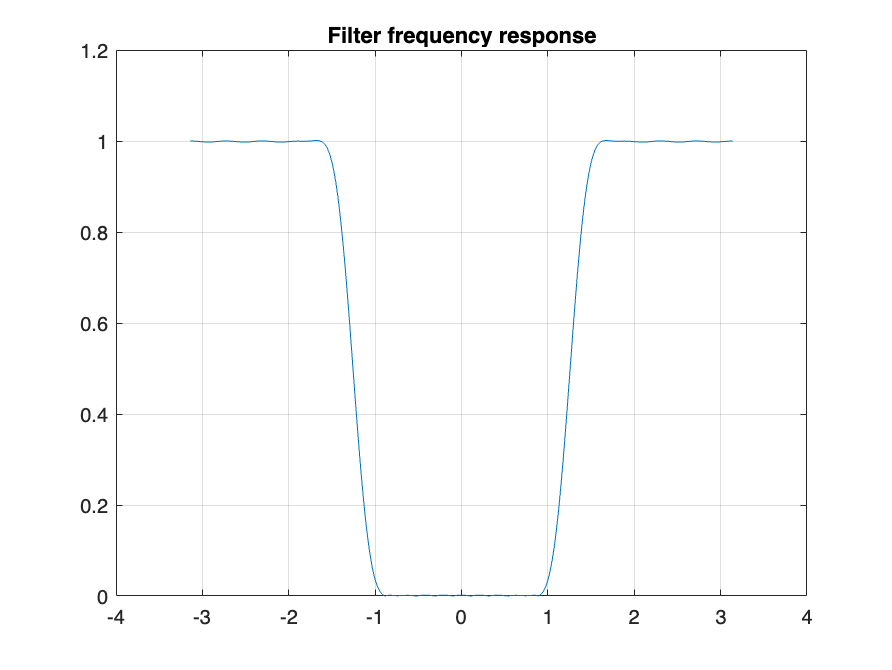


NumFFT = 4096;
Freqs = linspace(-pi,pi,NumFFT);

figure
plot(Freqs, abs(fftshift(fft(hc,NumFFT))));
title('Filter frequency response')
grid on

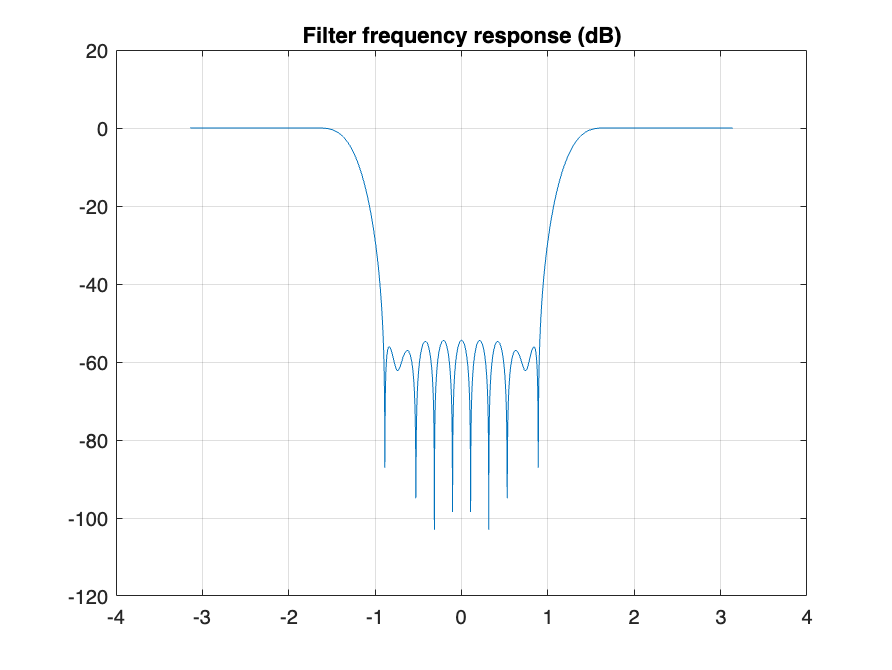


figure
plot(Freqs, 20*log10(abs(fftshift(fft(hc,NumFFT)))));
title('Filter frequency response (dB)')
grid on

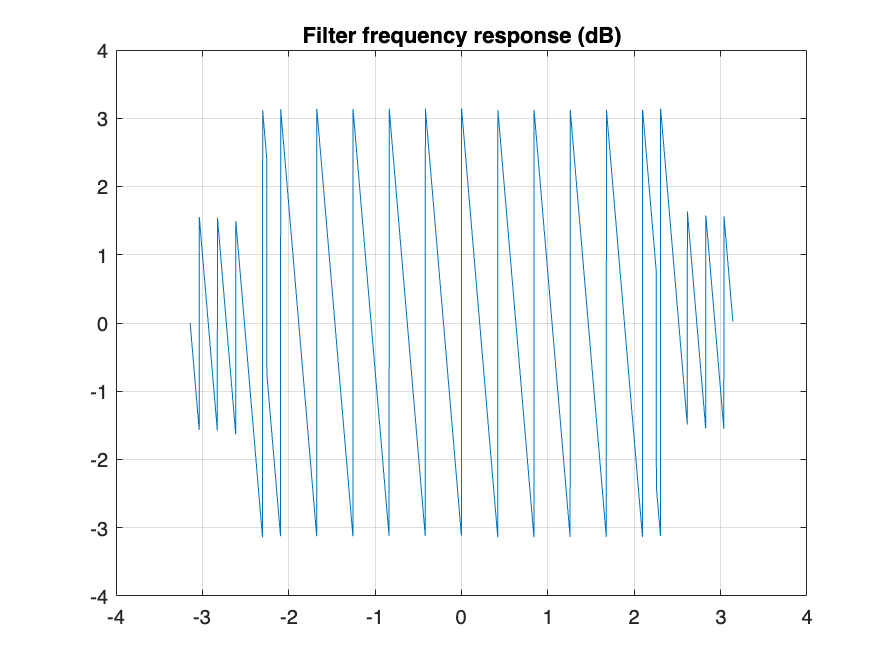


figure
plot(Freqs, angle(fft(hc,NumFFT)));
title('Filter frequency response (dB)')
grid on

### firls(.)

h_low = firls(N-1,[0,0.1, 0.35, 1] , [1 1 0 0]);  %Χαμηλοπερατό
h_high = firls(N-1,[0,0.1, 0.35, 1] , [0 0 1 1]); %Υψηπερατό

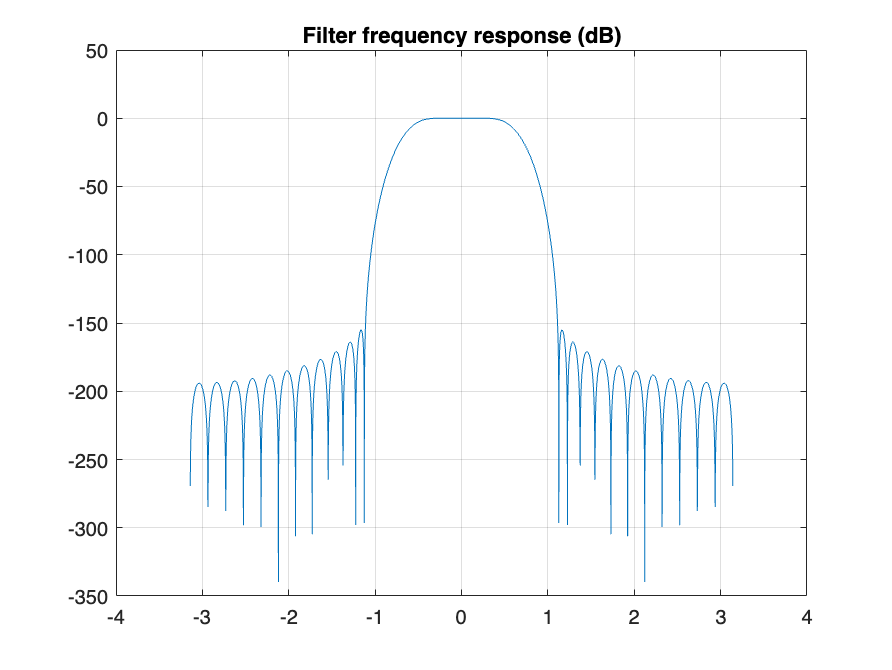


figure
plot(Freqs, 20*log(abs(fftshift(fft(h_low,NumFFT)))));
title('Filter frequency response (dB)')
grid on

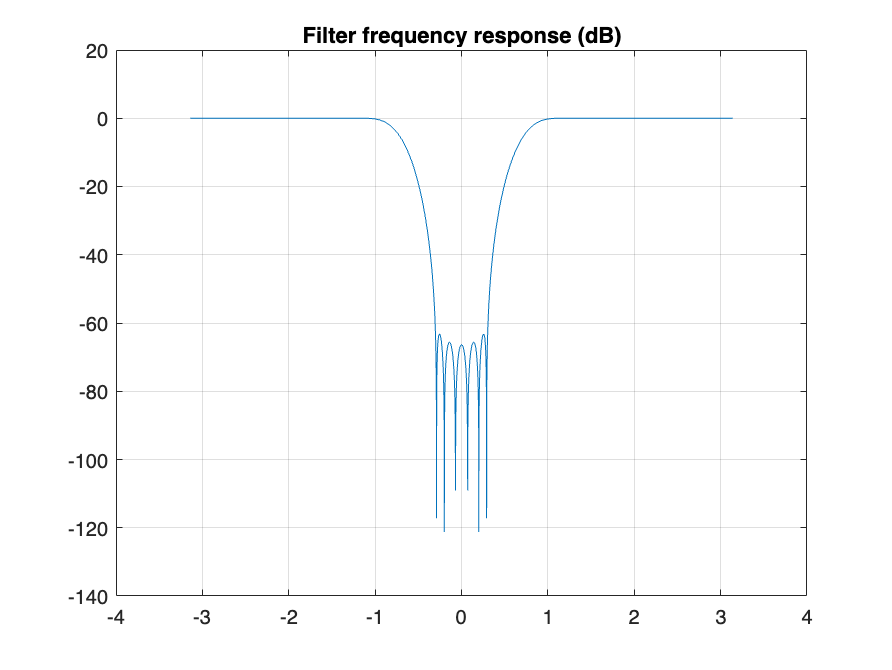


figure
plot(Freqs, 20*log10(abs(fftshift(fft(h_high,NumFFT)))));
title('Filter frequency response (dB)')
grid on

### firpm(.)

h_low = firpm(N-1,[0,0.1, 0.35, 1] , [1 1 0 0]);  %Χαμηλοπερατό
h_high = firpm(N-1,[0,0.1, 0.35, 1] , [0 0 1 1]); %Υψηπερατό

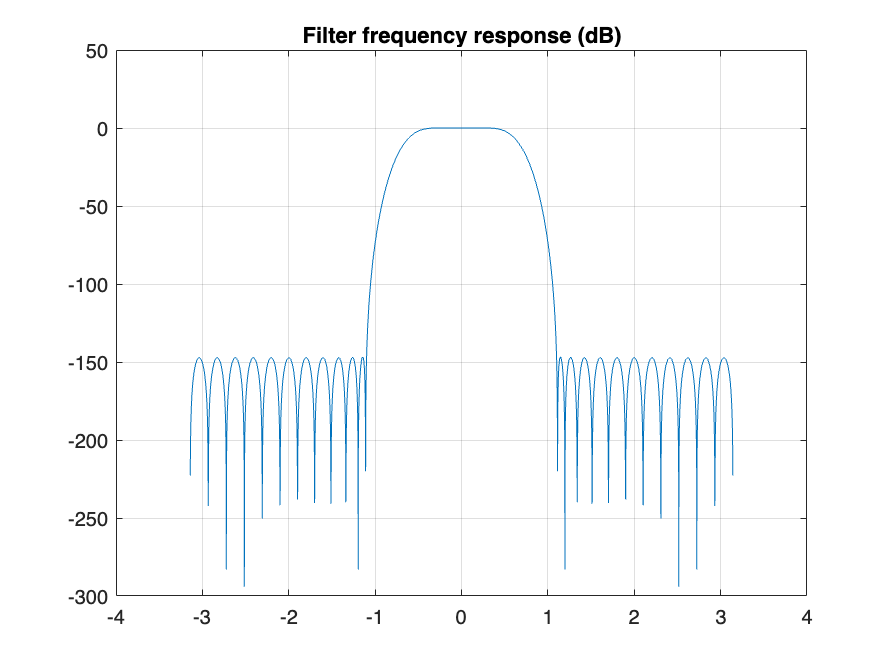


figure
plot(Freqs, 20*log(abs(fftshift(fft(h_low,NumFFT)))));
title('Filter frequency response (dB)')
grid on

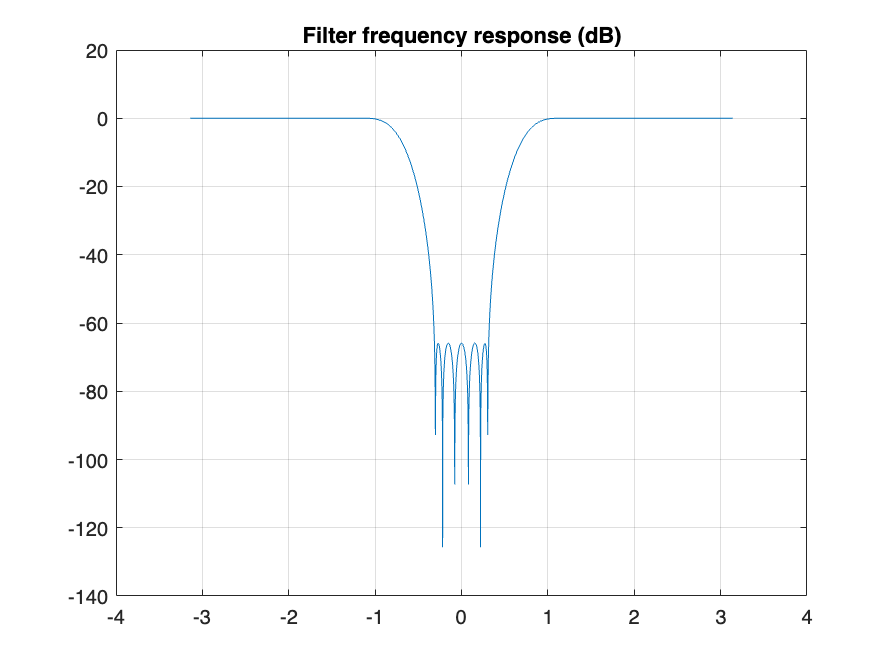


figure
plot(Freqs, 20*log10(abs(fftshift(fft(h_high,NumFFT)))));
title('Filter frequency response (dB)')
grid on

## Άσκηση 2